clear all
close all

addpath("Immagini\07_snr")

RO_noise_hard = [];
RO_noise_error = [];

RO_error = @(x,n) x./(sqrt(2*(n-1))*sqrt(2));

RO_1 = importdata("binning_1.asc");
RO_1 = RO_1(:,2:end);

RO_2 = importdata("binning_1_2.asc");
RO_2 = RO_2(:,2:end);

diff_image = RO_2-RO_1;

std_RO = std2(diff_image)*3.35;

RO_noise = std_RO/sqrt(2);
RO_noise_hard = [RO_noise_hard; RO_noise];

n = numel(diff_image);
RO_error_1 = RO_error(RO_noise,n);
RO_noise_error = [RO_noise_error; RO_error_1];

RO_1 = importdata("binning_2.asc");
RO_1 = RO_1(:,2:end);

RO_2 = importdata("binning_2_2.asc");
RO_2 = RO_2(:,2:end);

diff_image = RO_2-RO_1;

std_RO = std2(diff_image)*3.35;

RO_noise = std_RO/sqrt(2);
RO_noise_hard = [RO_noise_hard; RO_noise];

n = numel(diff_image);
RO_error_2 = RO_error(RO_noise,n);
RO_noise_error = [RO_noise_error; RO_error_2];

RO_1 = importdata("binning_4.asc");
RO_1 = RO_1(:,2:end);

RO_2 = importdata("binning_4_2.asc");
RO_2 = RO_2(:,2:end);

diff_image = RO_2-RO_1;

std_RO = std2(diff_image)*3.35;

RO_noise = std_RO/sqrt(2);
RO_noise_hard = [RO_noise_hard; RO_noise];

n = numel(diff_image);
RO_error_4 = RO_error(RO_noise,n);
RO_noise_error = [RO_noise_error; RO_error_4];

RO_1 = importdata("binning_8.asc");
RO_1 = RO_1(:,2:end);

RO_2 = importdata("binning_8_2.asc");
RO_2 = RO_2(:,2:end);

diff_image = RO_2-RO_1;

std_RO = std2(diff_image)*3.35;

RO_noise = std_RO/sqrt(2);
RO_noise_hard = [RO_noise_hard; RO_noise];

n = numel(diff_image);
RO_error_8 = RO_error(RO_noise,n);
RO_noise_error = [RO_noise_error; RO_error_8];

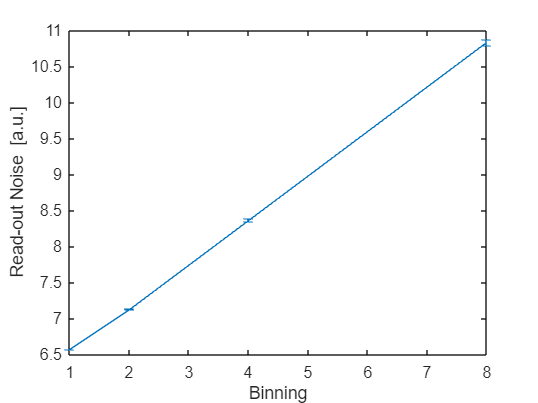

binning = [1; 2; 4; 8];

errorbar(binning, RO_noise_hard, RO_noise_error)
xlabel("Binning")
ylabel("Read-out Noise  [a.u.]")